clc;
clear all;
close all;
tic

% number of tx antennas
numTx = 8;
% number of rx antennas
numRx = 8;

% modulation order (16-QAM)
M = 16;
% number of transmitted symbols
% num_symbols = numTx * numRx * 10^2
% num_symbols = 1024*10^1;
% num_symbols = 49152; % 8 * 12 * 16 * 32
num_symbols = 24576; % 16 * 16 * 12 * 8
% 196608
% generate random symbols
symbols = randi([0 M-1], 1, num_symbols);

% array of ones with length equal to number of tx antennas
deltas = ones(1,numTx);

% points to plot
points = 20;
snr_min = 15;
snr_max = 35;
% generates an array of SNR values in the range [snr_min, snr_max] with a length equal to points
snr=linspace(snr_min,snr_max,points);
% array of zeros with length equal to the length of SNR values
ser=zeros(1,length(snr));

% modulate input signal x using QAM with specified modulation order M
xmod = qammod(symbols, M);

% reshape xmod into a matrix with number of rows equal to number of tx antennas and 
% number of columns equal to number of symbols/number of tx antennas
xmod=reshape(xmod,numTx,num_symbols/numTx);
% Kronecker tensor product of xmod and deltas
xmod=kron(xmod,deltas);

% initialize the matrix h to represent Rayleigh channel fading
% each row of h represents a fading channel between a tx antenna and a rx antenna
h = zeros(numTx * numRx, num_symbols/numRx);
% loop over the number of tx * rx fading channels
for l=1:(numTx*numRx)
    % generate a random channel for each fading channel using normal distribution
    h(l,:)=(1/sqrt(2)) * (randn(1,num_symbols/numRx) + 1i * randn(1,num_symbols/numRx));
end

% reshape h into a matrix with number of rows equal to number of tx antennas and number of columns equal to number of symbols
H = reshape(h, numTx, num_symbols);
% calculate the dot product of H and xmod and sum on the columns
tmp = sum(H .* xmod,1);
% reshape the result into a matrix with number of rows equal to number of rx antennas and number of columns equal to number of symbols/number of rx antennas
y = reshape(tmp, numRx, num_symbols/numRx);
% reshape h into a 3D matrix with dimensions equal to number of tx antennas, number of rx antennas, and number of symbols/number of rx antennas
H=reshape(h,numTx,numRx,num_symbols/numRx);

for k=1:length(snr) % loop through each snr value
    N1 = 1 / sqrt(2) * (randn(1,num_symbols)+1i * randn(1,num_symbols)); % generate noise signal
    N1 = reshape(N1, numRx, num_symbols/numRx); % reshape the noise signal
     
    ynoisy=y+10^(-(snr(k)-10 * log10(M))/20) *N1; % add noise to received signal
    ynoisy=reshape(ynoisy,numRx,1,num_symbols/numRx); % reshape the received signal with noise
    
    y_final = []; % initialize the final demodulated signal
    for l=1:num_symbols/numRx % loop through each symbol
        
        % r_counter is a 'counter' of how many times a certain receiver has been selected. 
        % Initially, all elements of r_counter are set to zero. 
        % The purpose of r_counter is to keep track of which receivers have already been selected so 
        % that they are not selected again.
        r_counter = zeros(numRx,1); % initialize r_counter
        
        r = ynoisy(:,:,l); % get the received signal for this symbol
        Heq = transpose(H(:,:,l)); % get the channel matrix for this symbol
        
        % In each iteration the minimum value of b is selected and the corresponding receiver is chosen. 
        % The value of c corresponding to the selected receiver is set to a large value so that this receiver 
        % is not selected again. The selected symbol is demodulated and the receiver is removed from 
        % the consideration by setting its corresponding column of Heq to 0.
        for p=1:numRx % loop through each receive antenna
            B = pinv(Heq); % calculate the pseudo-inverse of Heq
            b = abs(B .* B); % calculate the magnitude square of B
            
            temp_sum = zeros(numRx, 1); % initialize temp_sum
            for q=1:numRx/2 % loop through half the receive antennas
                temp_sum = temp_sum + b(:,q); % add the magnitude square of each column
            end
            b = temp_sum; % store the sum of magnitude square
            b = b + r_counter; % add r_counter to b
            % minimum value of b and respective index
            [min_b, index_min_b] = min(b,[],1); % find the minimum value and its index
            r_counter(index_min_b)=100; % set the corresponding value in r_counter to 100
            temp=qamdemod(B(index_min_b,:) * r,M); % demodulate the received signal
            ydemod(index_min_b)=temp; % store the demodulated symbol
            r=r-qammod(temp,M) .* Heq(:,index_min_b); % update the received signal
            Heq(:,index_min_b)=0; % set the corresponding column in Heq to 0
        end
        y_final=[y_final,ydemod]; % add the demodulated symbols to the final demodulated signal
    end
    [num, ty]=symerr(symbols,y_final); % calculate the number of symbol errors
    ser(k)=ty/log2(M); % store the symbol error rate
end

for k=1:length(snr)
    N1 = 1 / sqrt(2) * (randn(1,num_symbols)+1i*randn(1,num_symbols));
    N1 = reshape(N1, numRx, num_symbols/numRx);
    
    ynoisy=y+10^(-(snr(k)-10*log10(M))/20)*N1;
    ynoisy=reshape(ynoisy,numRx,1,num_symbols/numRx);
    
    B=[];
    rcvd=[];
    
    for l=1:num_symbols/numRx
        
        Heq=transpose(H(:,:,l));
        B=pinv(Heq);
        rcvd=[rcvd,B*ynoisy(:,:,l)];
    end
    
    final_y=qamdemod(reshape(rcvd,1,num_symbols),M);
%     [num, ser(k)]=symerr(symbols(end-(num_symbols*numTx/numRx)+1:end),final_y);
    [num, ty]=symerr(symbols,final_y);
    ser_zf(k)=ty/log2(M);
end

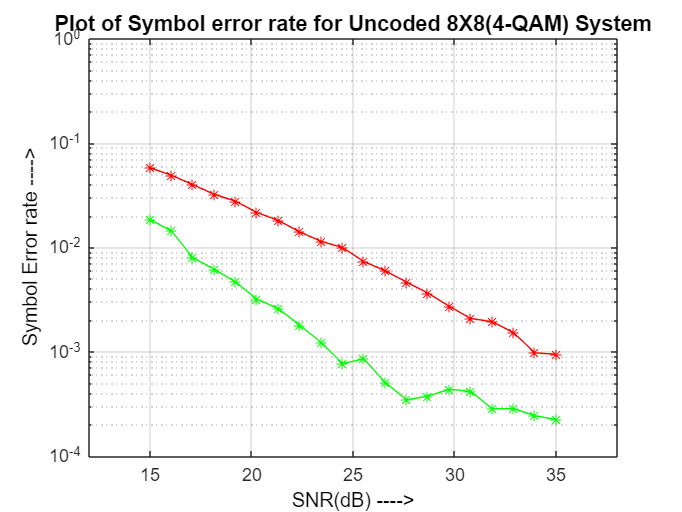

semilogy(snr,ser,'g-*');
grid on;hold on;
semilogy(snr,ser_zf,'r-*');
title('Plot of Symbol error rate for Uncoded 8X8(4-QAM) System','FontSize',12);
% legend('sim (nTx=8, nRx=8, Uncoded(4-QAM)) Using V-Blast/ZF','location','southwest');
xlabel('SNR(dB) ---->','Color','k','FontSize',11);
ylabel('Symbol Error rate ---->','Color','k','FontSize',11);
xlim([snr_min-3 snr_max+3])
ylim([10^-4 10^0])

toc

Elapsed time is 147.880925 seconds.
